# EPANET WQ Tests | BWFLnet_Sept2021

#### Prepared by: Yuanfei Wang

#### Date: 17 June 2022

clc
clear
close all

### Model Setup and Initialisation

Initialisation of EPANET Matlab toolkit and loading of .net file.

epanet_path = 'E:\Program Files\MATLAB\R2021b\toolbox\epanet\EPANET-Matlab-Toolkit-master';
net_id = 'BWFLnet_Sept2021';
run( [epanet_path,'\start_toolkit'])

EPANET-MATLAB Toolkit Paths Loaded.


net = epanet([net_id,'.inp']);

EPANET version {20200} loaded (EMT version {v2.2.0}).
Loading File "BWFLnet_Sept2021.inp"...
Input File "BWFLnet_Sept2021.inp" loaded sucessfuly.


### Water Age Simulation

Load network data and setup general water age simulation parameters.

% Save element count variables
nt = net.getTimeSimulationDuration./3600; % number of time steps in hours
nn = net.NodeJunctionCount;
n0 = net.NodeReservoirCount;
np = net.LinkCount; % count of pipes and valves
D = net.getLinkDiameter';

% Save node index vectors
Reservoir_Idx = net.getNodeReservoirIndex;
Junction_Idx = net.getNodeJunctionIndex;

% Initialise EPANET simulation type
net.setQualityType('Age');
net.setNodeSourceQuality(1:nn+n0,zeros(nn+n0,1)); % set all node source quality to zero

% Specify hydraulic and quality time steps (in seconds)
net.setTimeQualityStep(15*60); % 15 minute quality time steps
net.setTimeHydraulicStep(15*60); % 15 minute hydraulic time steps
days = 5; % simulation duration in days; change this variable to change overall simualtion time
net.setTimeSimulationDuration(days*(nt*3600)); % load modified simulation duration from initial .inp file

quality_res_age = net.getComputedQualityTimeSeries;

% Assign quality results to network elements
c_nodes_age = quality_res_age.NodeQuality';
c_pipes_age = quality_res_age.LinkQuality';
c_time_age = quality_res_age.Time./3600';

Load network data and setup general water age simulation parameters.

% Find the maximum water age and abnormal nodes (zero demand and zero age)
% Find the maximum water age
c_limit = 0.01

c_limit = 0.0100

c_nodes_maxage = zeros(size(c_nodes_age,1),1);
for i = 1:size(c_nodes_age,1)
    c_nodes_maxage(i,1) = max(c_nodes_age(i,:));
end
c_nodes_finalage = sort(c_nodes_maxage);

for i = 1:size(c_nodes_age,1)
    for j = 1:size(c_nodes_age,2)
        if c_nodes_age(i,j) == c_nodes_finalage(nn,1)
            c_nodes_maxageIdx = i;
            break;
        end
    end
end
c_maxnode_age = c_nodes_age(c_nodes_maxageIdx,:)';
for i = 1:size(c_maxnode_age,1)
    if abs(c_maxnode_age(i,1) - c_time_age(i,1)) > c_limit
        MaxTime = c_maxnode_age(i,1);
        break
    end
end
fprintf('The maximum simulation time before periodic behaviour in the network is %.4f', MaxTime);

The maximum simulation time before periodic behaviour in the network is 63.2303

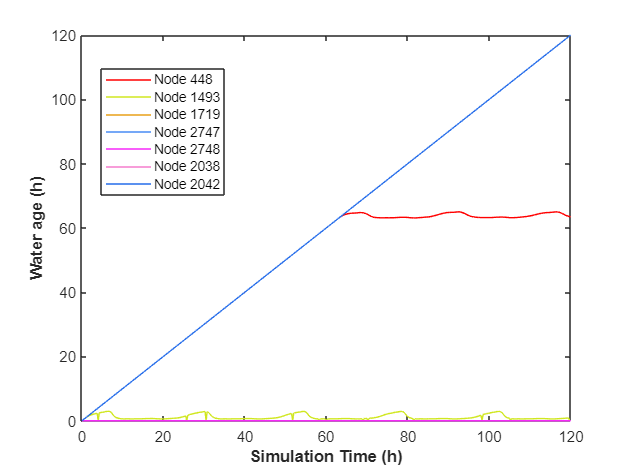


% Abonormal nodes
c_nodes_abnormalIdx = [];
c_nodes_abnormalIdx = [c_nodes_abnormalIdx;find(c_nodes_age(:,end) == 0)];
c_nodes_abnormalIdx = [c_nodes_abnormalIdx;find(abs(c_nodes_age(:,end) - double(days*nt)) <= c_limit)];

for i = 1:length(c_nodes_abnormalIdx)
    Junc_zero_Name{i} = sprintf('Node %d',c_nodes_abnormalIdx(i));
end
for i = 1:length(c_nodes_maxageIdx)
    Junc_max_Name{i} = sprintf('Node %d',c_nodes_maxageIdx(i));
end

% Plot the node with zero demand and largest water age
figure,
plot(0:0.25:days*24,c_nodes_age(c_nodes_maxageIdx,:)','-b','Color','r')
for i = 1:length(c_nodes_abnormalIdx)
    hold on
    plot(0:0.25:days*24,c_nodes_age(c_nodes_abnormalIdx(i),:)','-b','Color',[rand(),rand(),rand()]);
end

xlabel('Simulation Time (h)','FontWeight','bold')
ylabel('Water age (h)','FontWeight','bold')
legend([Junc_max_Name,Junc_zero_Name],'location','best')

% Test the abnormal nodes
c_pipes_abnormalIdx = [];
c_pipes_abnormalIdx = [c_pipes_abnormalIdx;find(c_pipes_age(:,end) == 0)];
c_pipes_abnormalIdx = [c_pipes_abnormalIdx;find(abs(c_pipes_age(:,end) - double(days*nt)) <= c_limit)];

% Test node 1493
LinkNodeIdx = net.getLinkNodesIndex;
LinktoNode1493 = find(LinkNodeIdx(:,2) == 1493);


### Chlorine Simulation

Load network data and setup general chemical simulation parameters.

% Initialise EPANET simulation type
net.setQualityType('Chemical','mg/L');
net.setNodeSourceQuality(1:nn+n0,zeros(nn+n0,1)); % set all node source quality to zero

Assign chlorine decay parameters.

% Link bulk reaction coefficients
lambda = 0.5*ones(np,1); % units of days^-1
net.setLinkBulkReactionCoeff(1:np, -lambda);
net.setOptionsPipeBulkReactionOrder(1);

% Link wall decay reaction coefficients... apply by pipe size for S&G?
% theta = ones(np,1); % units of m/day
% for k = 1:np
%     if D(k) <= 75
%         theta(k) = 0.25;
%     elseif D(k) > 75 && D(k) <= 150
%         theta(k) = 0.175;
%     elseif D(k) > 150 && D(k) <= 250
%         theta(k) = 0.1;
%     else
%         theta(k) = 0.05;
%     end
% end
% 
% net.setLinkWallReactionCoeff(1:np, -theta);
% net.setOptionsPipeWallReactionOrder(1);

% Initial concentrations at nodes (mg/L)
c0 = zeros(nn+n0,nt);
net.setNodeInitialQuality(net.NodeIndex,c0);

% Assign source chlorine with time varying pattern
cext = ones(n0,4*days*nt);

% Constant source concentration for n0 reservoirs
% cext = cext*0.25;

% Varying source concentration by source element
source_c = [1.00, 0.85];

Change the chlorine pattern, whether a spike set or not.

for j = 1:n0
    cext(j,:) = source_c(j)*cext(j,:);
end

% Varying source concentration by source element with
% concentration spike (pulse) at t = 12
% t = 144;
% for i = 1:4*days*nt
%     for j = 1:n0
%         if i == t
%             cext(j,i) = 1*cext(j,i); % Pulse of 1 mg/L
%         else
%             cext(j,i) = source_c(j)*cext(j,i);
%         end
%     end
% end

base_cext = ones(n0,1); 
pattern_cext = cext./(base_cext*ones(1,size(cext,2))); % extend vector over nt columns 


% For loop to assign new patterns to source contrations at reservoirs and
% source type
for i=1:n0
    patternId = sprintf('Res_C_%d',i);
    net.addPattern(patternId,pattern_cext(i,:));
    net.setNodeSourcePatternIndex(net.NodeReservoirIndex(i),net.getPatternIndex(patternId));
    net.setNodeSourceQuality(net.NodeReservoirIndex(i),base_cext(i));
    net.setNodeSourceType(net.NodeReservoirIndex(i),'CONCEN');  
end

### Results from EPANET Simulation

Simulate hydraulic and quality analyses using EPANET's solvers.

hydraulic_res = net.getComputedHydraulicTimeSeries;
quality_res = net.getComputedQualityTimeSeries;

% Assign hydraulic results to network elements
h = hydraulic_res.Head(1:4*nt*days,1:nn).';
q = 1e-3*hydraulic_res.Flow(1:4*nt*days,:).';

% Assign quality results to network elements
c_nodes = quality_res.NodeQuality';
c_pipes = quality_res.LinkQuality';

### Graph Creation

Use graph theory to plot network connectivity and spatial coordinates.

% Create A12 and A10 incidence matrices
LinkNodesList = net.getLinkNodesIndex;

A = zeros(np,nn+n0);
for k=1:np
    i = LinkNodesList(k,1);
    j = LinkNodesList(k,2);
    A(k,i) = -1;
    A(k,j) = 1;
end

A12 = A(:,Junction_Idx);
A10 = A(:,Reservoir_Idx);
A12 = sparse(A12);
A10 = sparse(A10);

% Obstain node XY and elevation information
XY = zeros(nn+n0,2);
XY(:,1) = net.getNodeCoordinates{1};
XY(:,2) = net.getNodeCoordinates{2};
elev = double(net.getNodeElevations(Junction_Idx))';

% Create adjacency matrix
A = [A12,A10];
AdjA = sparse(size(A,2),size(A,2));

for k = 1:size(A,1)
    node_in = find(A(k,:) == -1);
    node_out = find(A(k,:) == 1);
    AdjA(node_in,node_out) = 1;
    AdjA(node_out,node_in) = 1;
end
gr = graph(AdjA);

### Results Plotting

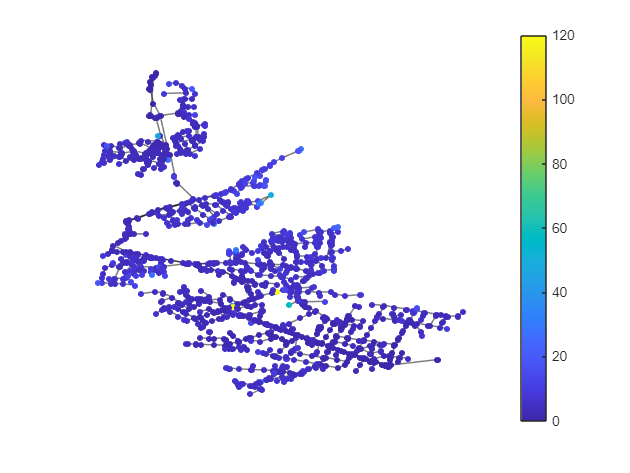

% Plot of network with zero demand junctions for visualisation
figure
i = 481;
p1 = plot(gr);
p1.XData = XY(:,1);
p1.YData = XY(:,2);
p1.LineWidth = 1;
p1.EdgeColor = 'k';
p1.MarkerSize = 3;
p1.NodeColor = 'b';
p1.NodeLabel = '';
% highlight(p1,c_nodes_abnormalIdx,'NodeColor','r','MarkerSize',8);
% labelnode(p1,c_nodes_abnormalIdx,Junc_zero_Name);
% highlight(p1,c_nodes_maxageIdx,'NodeColor','yellow','MarkerSize',8);
% labelnode(p1,c_nodes_maxageIdx,Junc_max_Name);
% highlight(p1,Reservoir_Idx,'NodeColor','k','Marker','s','MarkerSize',10);
% labelnode(p1,Reservoir_Idx,{'Reservoir','Reservoir'});
p1.NodeFontSize = 11;
p1.NodeLabelColor = [0.6350 0.0780 0.1840];
p1.NodeFontWeight = 'bold';
p1.NodeCData = c_nodes_age(:,i);
colorbar
axis('off')

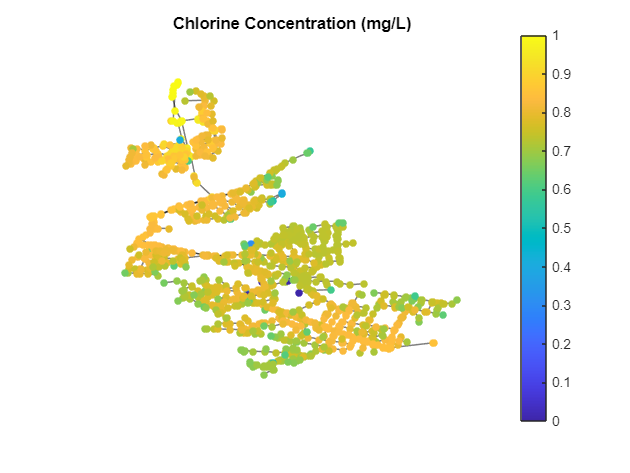


% Plot of Cl2 concentration distributed across network
% Select period to show results
i = 225;
figure
p2 = plot(gr);
p2.XData = XY(:,1);
p2.YData = XY(:,2);
p2.LineWidth = 1;
p2.EdgeColor = 'k';
p2.MarkerSize = 4;
p2.NodeLabel = '';

p2.NodeCData = c_nodes(:,i);

colorbar
axis('off')
title('Chlorine Concentration (mg/L)')

Plot time series of chlorine concentration for select junctions.

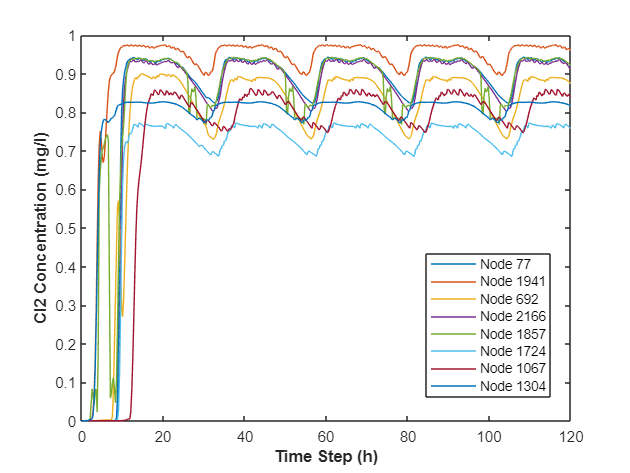

% Select junctions below
Junc_select = [77, 1941, 692, 2166, 1857, 1724, 1067, 1304];
for i = 1:length(Junc_select)
    Junct_Name{i} = sprintf('Node %d',Junc_select(i));
end
figure
for ii = 1:length(Junc_select)
        a = Junc_select(ii);
        plot(0:0.25:days*24,c_nodes(a,:)','-')
    hold on
end

legend(Junct_Name,'location','best');
xlabel('Time Step (h)','fontweight','bold')
ylabel('Cl2 Concentration (mg/l)','fontweight','bold')

### Trial-and-Error Calibration

Create a random matrix, assume we have no data, we create quality data based on the distance between the node and reservoir.

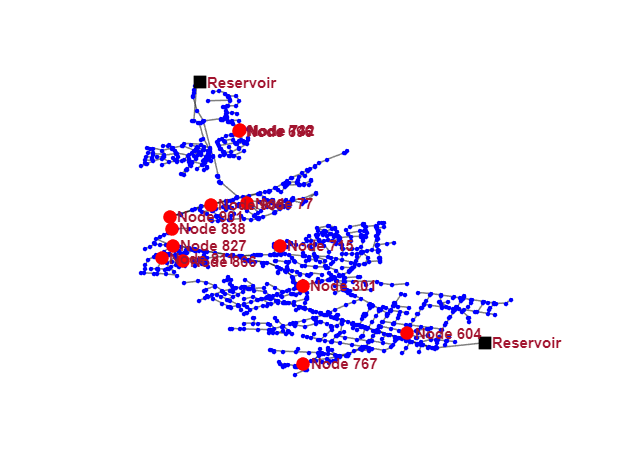

% Create the 14 sensor data
SensorIdx = [301,604,715,732,740,767,77,811,827,838,866,901,696,908];
qual_sim = c_nodes(SensorIdx,:); 
age_sim = c_nodes_age(SensorIdx,:);
age_mean = zeros(size(age_sim,1),1);
for i = 1:size(age_sim,1)
    age_mean(i,1) = mean(age_sim(i,:));
end

% Highlight sensors
for i = 1:length(SensorIdx)
    Junct_Sensor{i} = sprintf('Node %d',SensorIdx(i));
end

figure
p1 = plot(gr);
p1.XData = XY(:,1);
p1.YData = XY(:,2);
p1.LineWidth = 1;
p1.EdgeColor = 'k';
p1.MarkerSize = 2;
p1.NodeColor = 'b';
p1.NodeLabel = '';
highlight(p1,SensorIdx,'NodeColor','r','MarkerSize',8);
labelnode(p1,SensorIdx,Junct_Sensor);
highlight(p1,Reservoir_Idx,'NodeColor','k','Marker','s','MarkerSize',10);
labelnode(p1,Reservoir_Idx,{'Reservoir','Reservoir'});
p1.NodeFontSize = 10;
p1.NodeLabelColor = [0.6350 0.0780 0.1840];
p1.NodeFontWeight = 'bold';
axis('off')

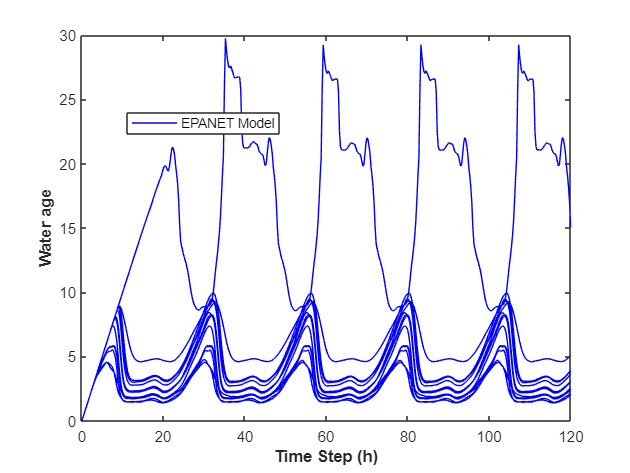

% Assign quality inversely proportional to the water age of 14
% sensors as the actual quality
qual_obs = (source_c(1)+source_c(2))./(1+age_sim);

% Plot the sensor water age
figure,
for i = 1:size(age_sim,1)
    plot(0:0.25:days*24,age_sim(i,:),'-b')
    hold on
end

xlabel('Time Step (h)','FontWeight','bold')
ylabel('Water age','FontWeight','bold')
legend('EPANET Model','location','best')

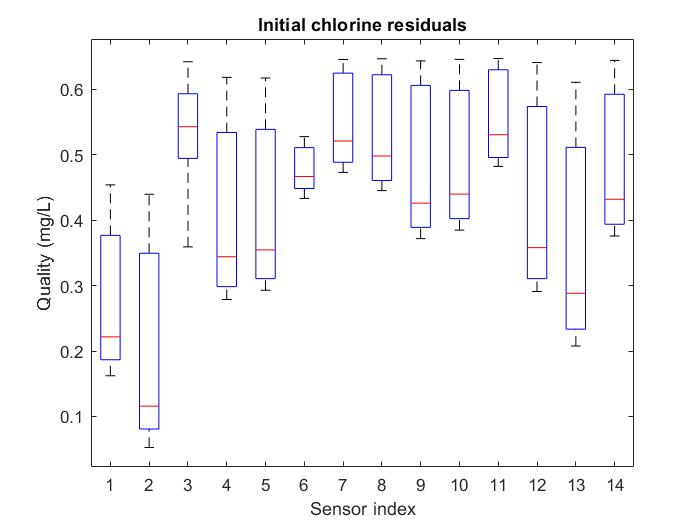

% day1 for stabilisation, day2 to day3 for train, day3 to day5 for
% validation
day_train = 2;
day_val = 3;
qual_train_sim = qual_sim(:,((day_train-1)*24*4+2):(day_train*24*4+1));
qual_train_obs = qual_obs(:,((day_train-1)*24*4+2):(day_train*24*4+1));
qual_val_sim = qual_sim(:,((day_val-1)*24*4+2):((day_val+2)*24*4+1));
qual_val_obs = qual_obs(:,((day_val-1)*24*4+2):((day_val+2)*24*4+1));
qual_residual = qual_train_sim - qual_train_obs;

% Mse function
mse_fun = @(sim, obs) (1/size(obs,1)/size(obs,2))*sum(sum((sim - obs).^2));

% Current mse
mse_train = mse_fun(qual_train_sim, qual_train_obs);

figure,boxplot(qual_residual');
xlabel('Sensor index')
ylabel('Quality (mg/L)')
title('Initial chlorine residuals')

One group calibration.

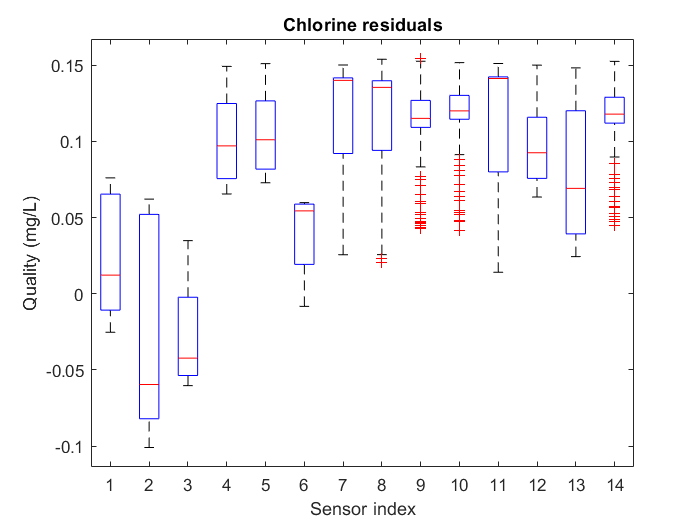

% Set a loop to determine the bulk decay coefficient
tic
MaxIter = 15;
lambdaIter = 1.5*ones(np,1);
mse_limit = 0.01;
mseIter = zeros(1,MaxIter);
for i = 1:MaxIter
    net.setLinkBulkReactionCoeff(1:np, -lambdaIter);
    quality_resIter = net.getComputedQualityTimeSeries;
    c_nodesIter = quality_resIter.NodeQuality';
    qual_simIter = c_nodesIter(SensorIdx,:); 
    qual_train_Iter = qual_simIter(:,((day_train-1)*24*4+2):(day_train*24*4+1));
    mse_trainIter = mse_fun(qual_train_Iter, qual_train_obs);
    mseIter(1,i) = mse_trainIter;
    if mse_trainIter <= mse_limit
        break;
    else
        lambdaIter = lambdaIter + 0.25;
    end
end
SimDuration_1group = toc;

% Set 1 group final Link bulk reaction coefficients
lambda2 = lambdaIter; % units of days^-1
net.setLinkBulkReactionCoeff(1:np, -lambda2);

% New result
quality_res2 = net.getComputedQualityTimeSeries;
c_nodes2 = quality_res2.NodeQuality';
qual_sim2 = c_nodes2(SensorIdx,:); 
qual_train_sim2 = qual_sim2(:,((day_train-1)*24*4+2):(day_train*24*4+1));
mse_train2 = mse_fun(qual_train_sim2, qual_train_obs);
qual_residual2 = qual_train_sim2 - qual_train_obs;

% Current plot
figure,boxplot(qual_residual2');
xlabel('Sensor index')
ylabel('Quality (mg/L)')
title('Chlorine residuals')

% Report the result
fprintf(['The residula chlorine at 14 sensors are as shown above, 1 group mse after' ...
    ' trial-and-error calibration is %.4f \n'], mse_train2);

The residula chlorine at 14 sensors are as shown above, 1 group mse after trial-and-error calibration is 0.0096 


Pipe diameter-based group calibration

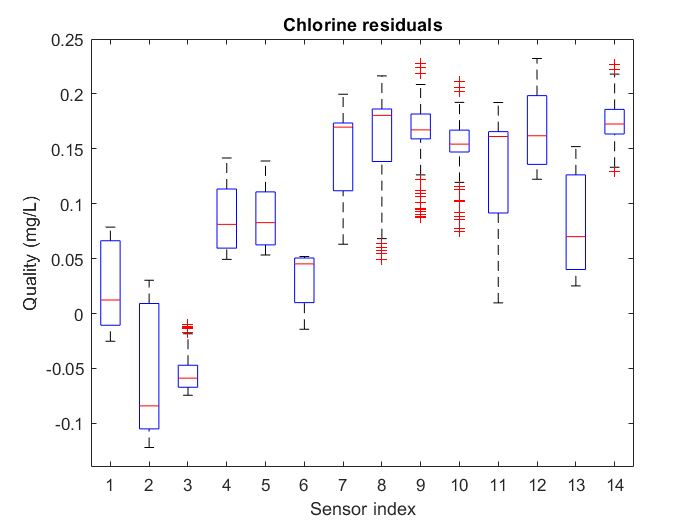

% Group the pipes according to the pipe diameter
tic
lambdaIter_dia_group = ones(np,1); % units of m/day
mseIter_group = zeros(1,MaxIter);

for k = 1:np
    if D(k) <= 75
        lambdaIter_dia_group(k) = 4.5;
    elseif D(k) > 75 && D(k) <= 150
        lambdaIter_dia_group(k) = 3.5;
    elseif D(k) > 150 && D(k) <= 250
        lambdaIter_dia_group(k) = 2.5;
    else
        lambdaIter_dia_group(k) = 1.5;
    end
end

net.setLinkBulkReactionCoeff(1:np, -lambdaIter_dia_group);

for i = 1:MaxIter
    net.setLinkBulkReactionCoeff(1:np, -lambdaIter_dia_group);
    quality_resIter_group = net.getComputedQualityTimeSeries;
    c_nodesIter_group = quality_resIter_group.NodeQuality';
    qual_simIter_group = c_nodesIter_group(SensorIdx,:); 
    qual_train_Iter_group = qual_simIter_group(:,((day_train-1)*24*4+2):(day_train*24*4+1));
    mse_trainIter_group = mse_fun(qual_train_Iter_group, qual_train_obs);
    mseIter_group(1,i) = mse_trainIter_group;
    if mse_trainIter_group <= mse_limit
        break;
    else
        lambdaIter_dia_group = lambdaIter_dia_group + 0.1;
    end
end
SimDuration_diagroup = toc;

% Set diameter based grouped final Link bulk reaction coefficients
lambda3 = lambdaIter_dia_group; % units of days^-1
net.setLinkBulkReactionCoeff(1:np, -lambda3);

% New result
quality_res3 = net.getComputedQualityTimeSeries;
c_nodes3 = quality_res3.NodeQuality';
qual_sim3 = c_nodes3(SensorIdx,:); 
qual_train_sim3 = qual_sim3(:,((day_train-1)*24*4+2):(day_train*24*4+1));
mse_train3 = mse_fun(qual_train_sim3, qual_train_obs);
qual_residual3 = qual_train_sim3 - qual_train_obs;

% Current plot
figure,boxplot(qual_residual3');
xlabel('Sensor index')
ylabel('Quality (mg/L)')
title('Chlorine residuals')

% Report the result
fprintf(['The residula chlorine at 14 sensors are as shown above, diameter-based grouped\n mse after' ...
    ' trial-and-error calibration is %.4f \n'], mse_train3);

The residula chlorine at 14 sensors are as shown above, diameter-based grouped
 mse after trial-and-error calibration is 0.0157 


### Trial-and-Error Validation

Use the quality data in the last three days to validate the chlorine decay parameters obtained through calibration.

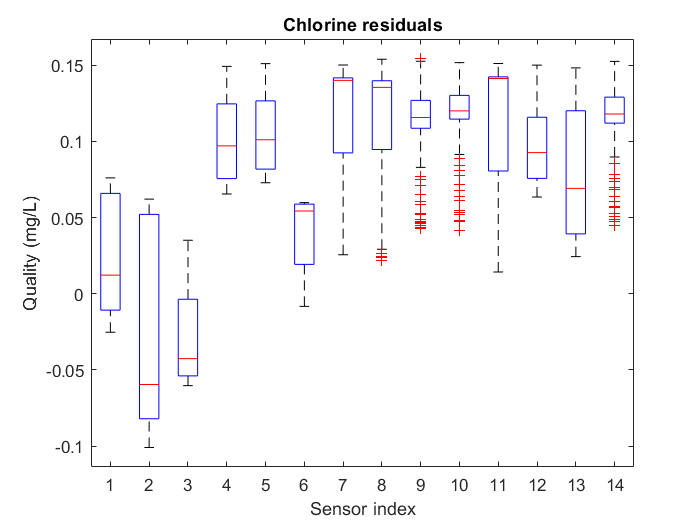

% 1 group model validation
qual_val_sim2 = qual_sim2(:,((day_val-1)*24*4+2):((day_val+2)*24*4+1));
mse_val2 = mse_fun(qual_val_sim2, qual_val_obs);
qual_val_residual2 = qual_val_sim2 - qual_val_obs;

% 1 group Validation plot
figure,boxplot(qual_val_residual2');
xlabel('Sensor index')
ylabel('Quality (mg/L)')
title('Chlorine residuals')

% Report the result
fprintf(['The residula chlorine at 14 sensors in the validation data are as shown above, \n' ...
    '1 group validation mse is %.4f \n'], mse_val2);

The residula chlorine at 14 sensors in the validation data are as shown above, 
1 group validation mse is 0.0096 


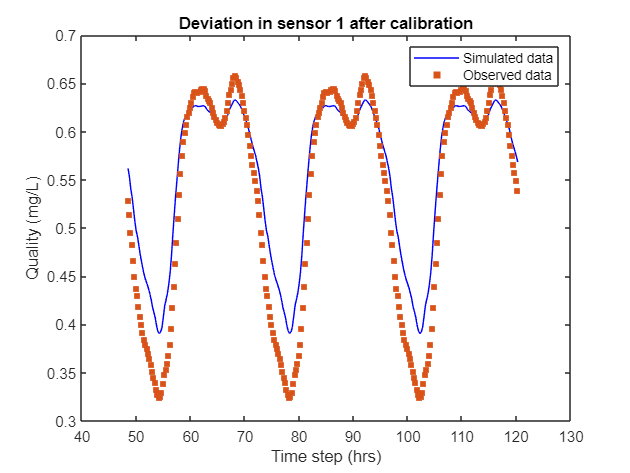


% Plot the calibrated quality-time figure at sensor1
figure,
plot(((day_val-1)*24*4+2)/4:0.25:((day_val+2)*24*4+1)/4,qual_val_sim2(1,:),'-b')
hold on
scatter(((day_val-1)*24*4+2)/4:0.25:((day_val+2)*24*4+1)/4,qual_val_obs(1,:),25,'filled','square')
legend({'Simulated data','Observed data'})
xlabel('Time step (hrs)')
ylabel('Quality (mg/L)')
title('Deviation in sensor 1 after calibration')

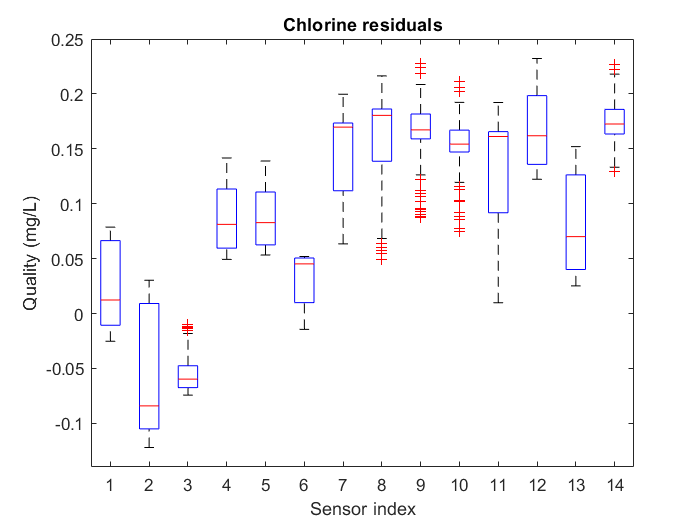

% Diameter-based group model validation
qual_val_sim3 = qual_sim3(:,((day_val-1)*24*4+2):((day_val+2)*24*4+1));
mse_val3 = mse_fun(qual_val_sim3, qual_val_obs);
qual_val_residual3 = qual_val_sim3 - qual_val_obs;

% Diameter-based Validation plot
figure,boxplot(qual_val_residual3');
xlabel('Sensor index')
ylabel('Quality (mg/L)')
title('Chlorine residuals')

% Report the result
fprintf(['The residula chlorine at 14 sensors in the validation data are as shown above, \n' ...
    'diameter-based group validation mse is %.4f \n'], mse_val3);

The residula chlorine at 14 sensors in the validation data are as shown above, 
diameter-based group validation mse is 0.0157 


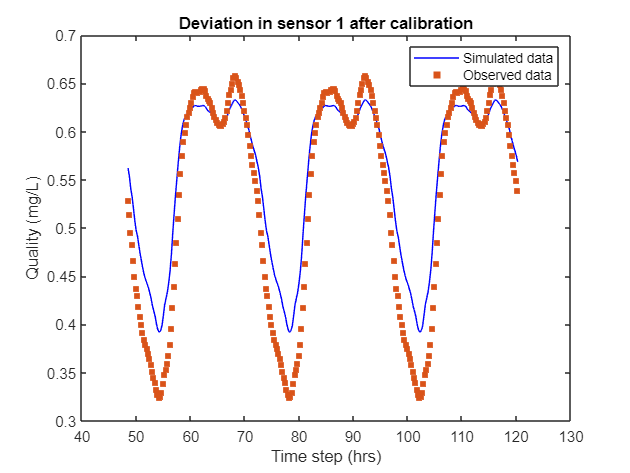


% Plot the calibrated quality-time figure at sensor1
figure,
plot(((day_val-1)*24*4+2)/4:0.25:((day_val+2)*24*4+1)/4,qual_val_sim3(1,:),'-b')
hold on
scatter(((day_val-1)*24*4+2)/4:0.25:((day_val+2)*24*4+1)/4,qual_val_obs(1,:),25,'filled','square')
legend({'Simulated data','Observed data'})
xlabel('Time step (hrs)')
ylabel('Quality (mg/L)')
title('Deviation in sensor 1 after calibration')